# Pulse detector reference

© 2019 The MathWorks, Inc.

This script creates the reference pulse detection algorithm and parameters needed by all the test bench steps.

## Create input stimulus

% Setup
clear; clc; close all;

% Create pulse to detect
rng('default');
PulseLen = 64;
theta = rand(PulseLen,1);
pulse = exp(1i*2*pi*theta);

% Insert pulse to Tx signal
rng('shuffle');
TxLen = 5000;
PulseLoc = randi(TxLen-PulseLen*2);

TxSignal = zeros(TxLen,1);
TxSignal(PulseLoc:PulseLoc+PulseLen-1) = pulse;

% Create Rx signal by adding noise
Noise = complex(randn(TxLen,1),randn(TxLen,1));
RxSignal = TxSignal + Noise;

% Scale Rx signal to +/- one
scale1 = max([abs(real(RxSignal)); abs(imag(RxSignal))]);
RxSignal = RxSignal/scale1;

## MATLAB golden reference

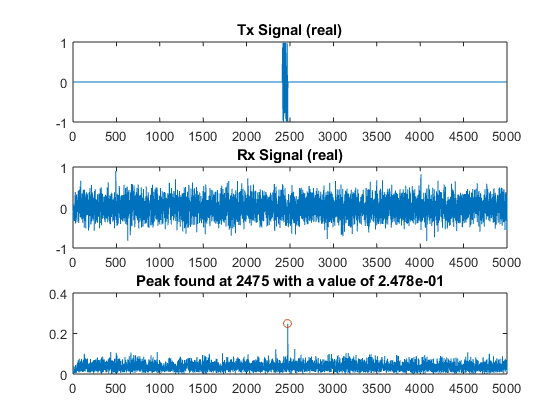

% Create matched filter coefficients
CorrFilter = conj(flip(pulse))/PulseLen;
rowCorrFilter = CorrFilter.';
% Correlate Rx signal against matched filter
FilterOut = filter(CorrFilter,1,RxSignal);

% Find peak magnitude & location
[peak, location] = max(abs(FilterOut));

% Print results
figure(1)
subplot(311); plot(real(TxSignal)); title('Tx Signal (real)');
subplot(312); plot(real(RxSignal)); title('Rx Signal (real)');

t = 1:length(FilterOut);
str = sprintf('Peak found at %d with a value of %.3d',location,peak);
subplot(313); plot(t,abs(FilterOut),location,peak,'o'); title(str);

## Hardware friendly implementation of peak finder

Instead of calculating the maximum value of the entire frame, we look for a local peak within a sliding window of the last 11 samples using the following criteria:

- The middle sample is the largest

- The middle sample is greater than a pre-defined threshold

WindowLen = 11;
MidIdx = ceil(WindowLen/2);
threshold = 0.03;

% Compute magnitude squared to avoid sqrt operation
MagSqOut = abs(FilterOut).^2;

% Sliding window operation
for n = 1:length(FilterOut)-WindowLen

    % Compare each value in the window to the middle sample via subtraction
    DataBuff = MagSqOut(n:n+WindowLen-1);
    MidSample = DataBuff(MidIdx);
    CompareOut = DataBuff - MidSample; % this is a vector

    % if all values in the result are negative and the middle sample is
    % greater than a threshold, it is a local max
    if all(CompareOut <= 0) && (MidSample > threshold)
        peak_2 = MidSample;
        location_2 = n + (MidIdx-1);
    end
end